# Nonlinear Figure of Merit

%
%	Sebastian C. Robarts 2024 - sebrobarts@gmail.com

%% Setup
close all; clear;
if gpuDeviceCount
	gpuDevice(1);
end
if size(groot().MonitorPositions,1) > 1
	set(0, 'DefaultFigurePosition', [groot().MonitorPositions(2,1:2)+50 900 450])
end
set(0, 'DefaultFigureColormap', magma)
set(0, 'DefaultLineLineWidth', 1)
format short g
fignum = 1;

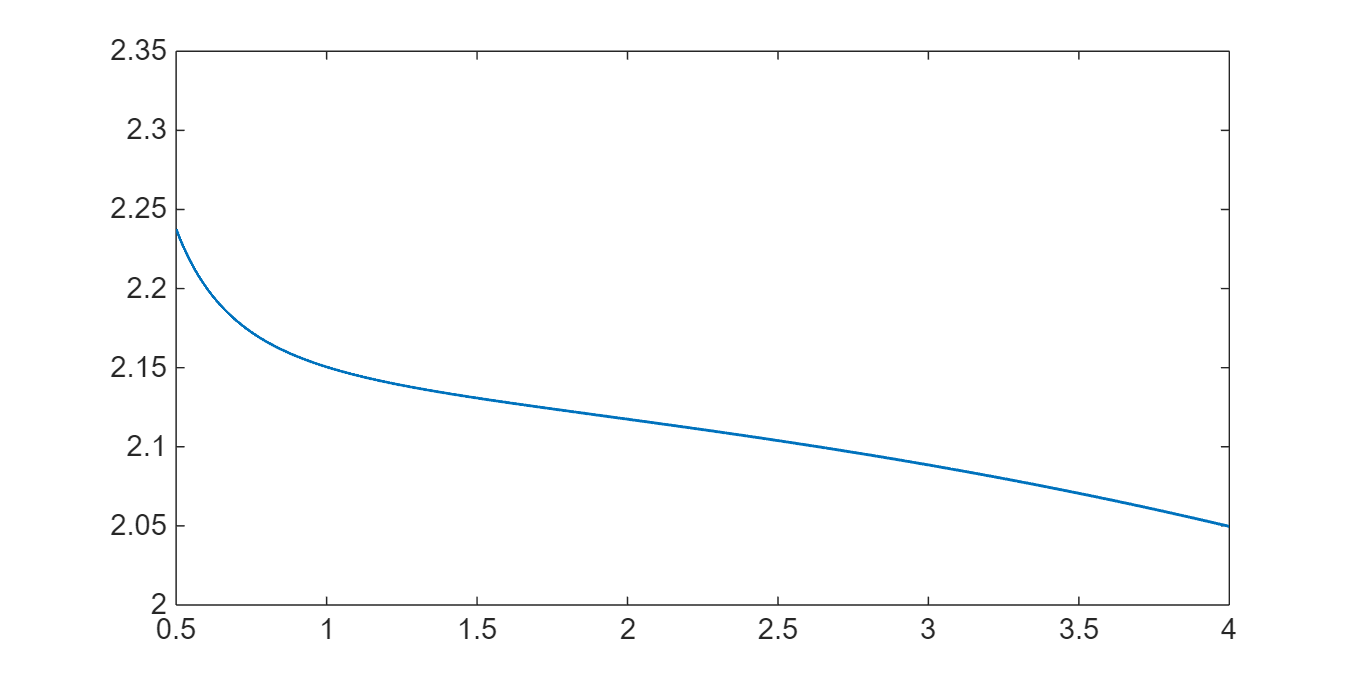

%%% Load Objects
load Chromacity_230042_9A_2.mat
load HCP_PPLN_fanout_Auskerry.mat

n_points = 2^11;
lambda_pump_central = 1.035; % [um]
simWin = SimWindow(lambda_pump_central*1e-6,n_points,[0.5,6].*1e3,0,"spec");
simWin.ref2max;

laser.Name = "Chromacity 230042 9A";
laser.Waist = 40e-6;

crystal.Chi2 = 2*25.3e-12;
crystal.Bulk.Temperature = 20;
crystal.simulate(simWin);
lam_um = ((simWin.LambdanmPlot.*1e-3));	% [um]  Ascending
pID = simWin.IsNumIndex;

figure
plot(lam_um,crystal.Bulk.RefractiveIndex(pID))
xlim([0.5 4])
ylim([2 2.35])

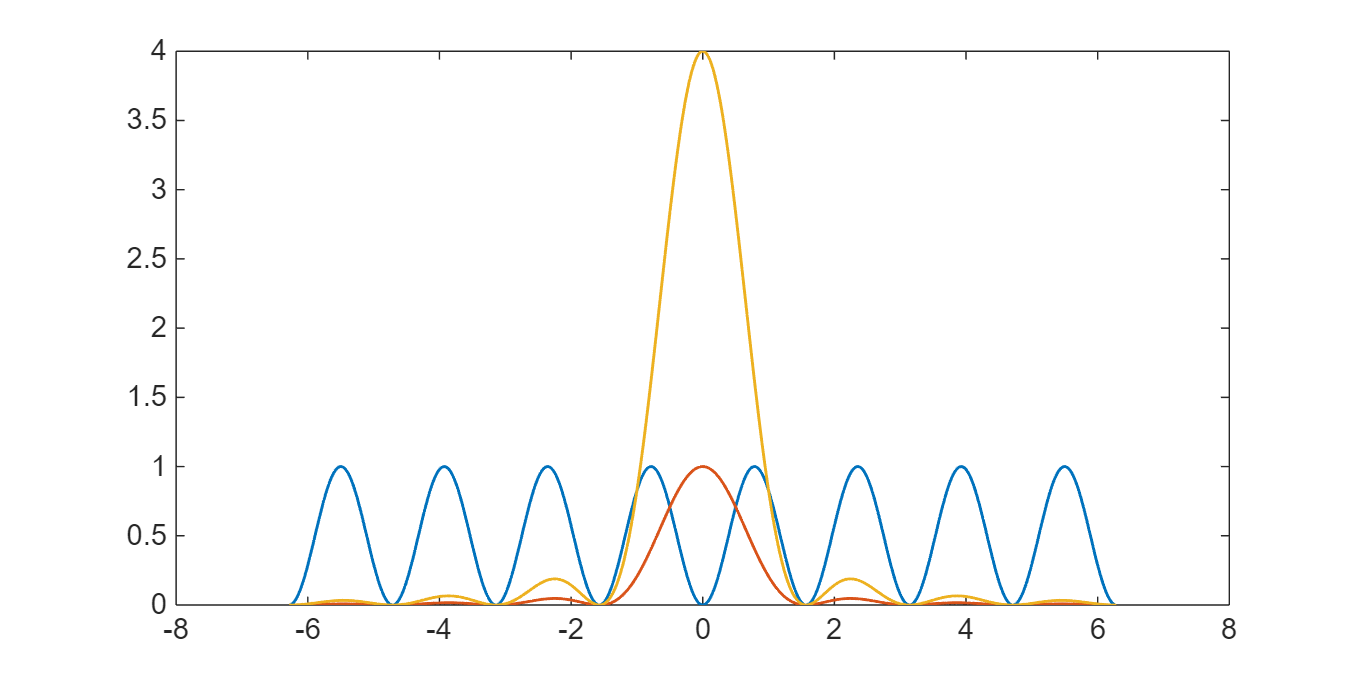

%% Sinc^2
L = 2;
dk = linspace(-4*pi,4*pi,1000)./2;
dkl = dk.*L;
sin2 = sin(dkl).^2;
sinc2 = sin2./(dkl.^2);
sincL2 = sin2./(dk.^2);

figure
plot(dk,[sin2; sinc2; sincL2])

%% FOM
deff = (crystal.Chi2 ./ pi);
deff_pm_V = deff .* 1e12;
% lam_p_um = laser.Wavelength .* 1e6;
% lam_p_um = 1;
lam_p_um = lam_um';

lam_dfg_um = dfg_lambda(lam_p_um,lam_um,lam_um);
[k_p,n_p] = kcalc(lam_p_um,crystal);
[k_dfg,n_dfg,w_dfg] = kcalc(lam_dfg_um,crystal);
[k_i,n_i] = kcalc(lam_um,crystal);
fom_dfg = (deff_pm_V.^2)./(n_p.*n_dfg.*n_i);
fom_dfg(lam_dfg_um==0) = 0;
conv_dfg = (deff.^2)./(n_p.*n_dfg.*n_i) .* w_dfg.^2;
conv_dfg(lam_dfg_um==0) = 0;
conv_dfg = 2 .* conv_dfg ./(eps0 .* c^3);
conv_dfg = conv_dfg .* crystal.Length.^2;

lam_sfg_um = sfg_lambda(lam_p_um,lam_um,lam_um);
[k_sfg,n_sfg,w_sfg] = kcalc(lam_sfg_um,crystal);
fom_sfg = (deff_pm_V.^2)./(n_p.*n_sfg.*n_i);
fom_sfg(lam_sfg_um==0) = 0;
conv_sfg = (deff.^2)./(n_p.*n_sfg.*n_i) .* w_sfg.^2;
conv_sfg(lam_sfg_um==0) = 0;
conv_sfg = 2 .* conv_sfg ./(eps0 .* c^3);

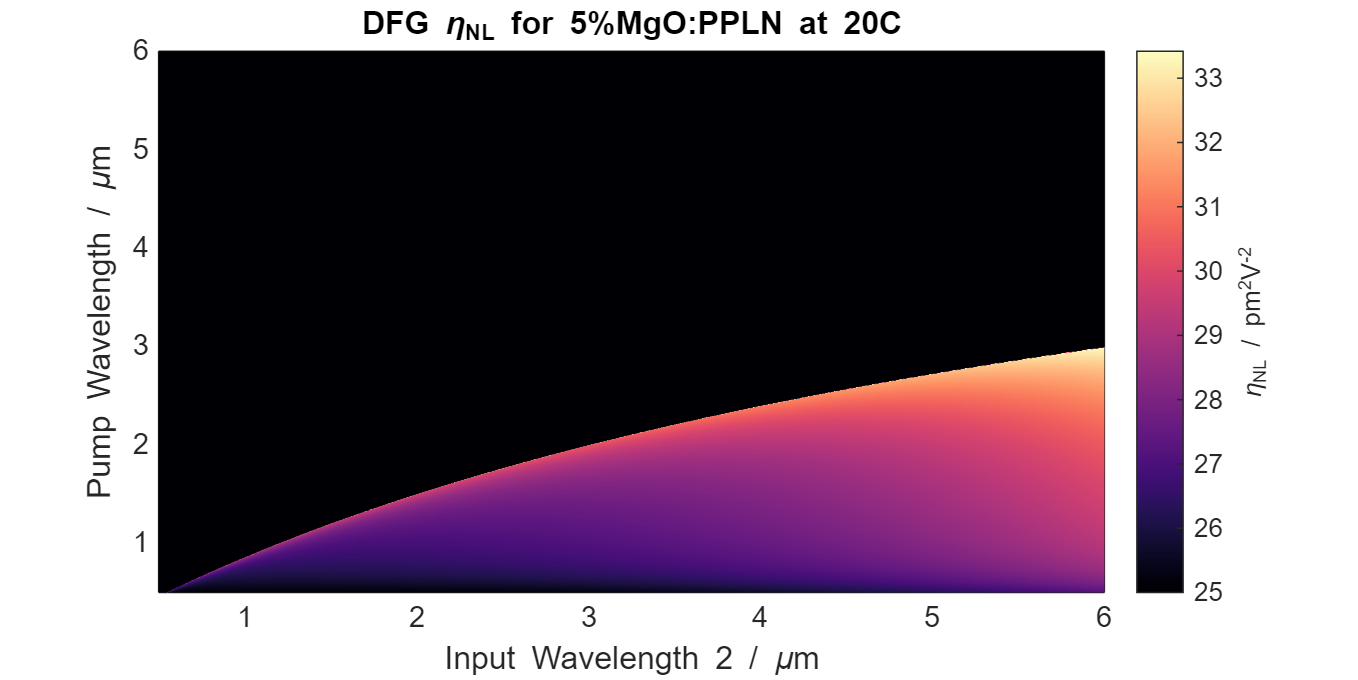

figure
if isscalar(lam_p_um)
	plot(lam_um,fom_dfg)
	xlim([lam_p_um 5])
else
	pcolor(lam_um,lam_um,fom_dfg)
	shading interp
	cb = colorbar;
	clims = clim;
	clims(1) = 25;
	clim(clims);
	cb.Label.String = "\eta_{NL} / pm^2V^{-2}";
	ylabel("Pump Wavelength / \mum")
end
xlabel("Input Wavelength 2 / \mum")
title("DFG \eta_{NL} for 5%MgO:PPLN at " + num2str(crystal.Bulk.Temperature,'%iC'))

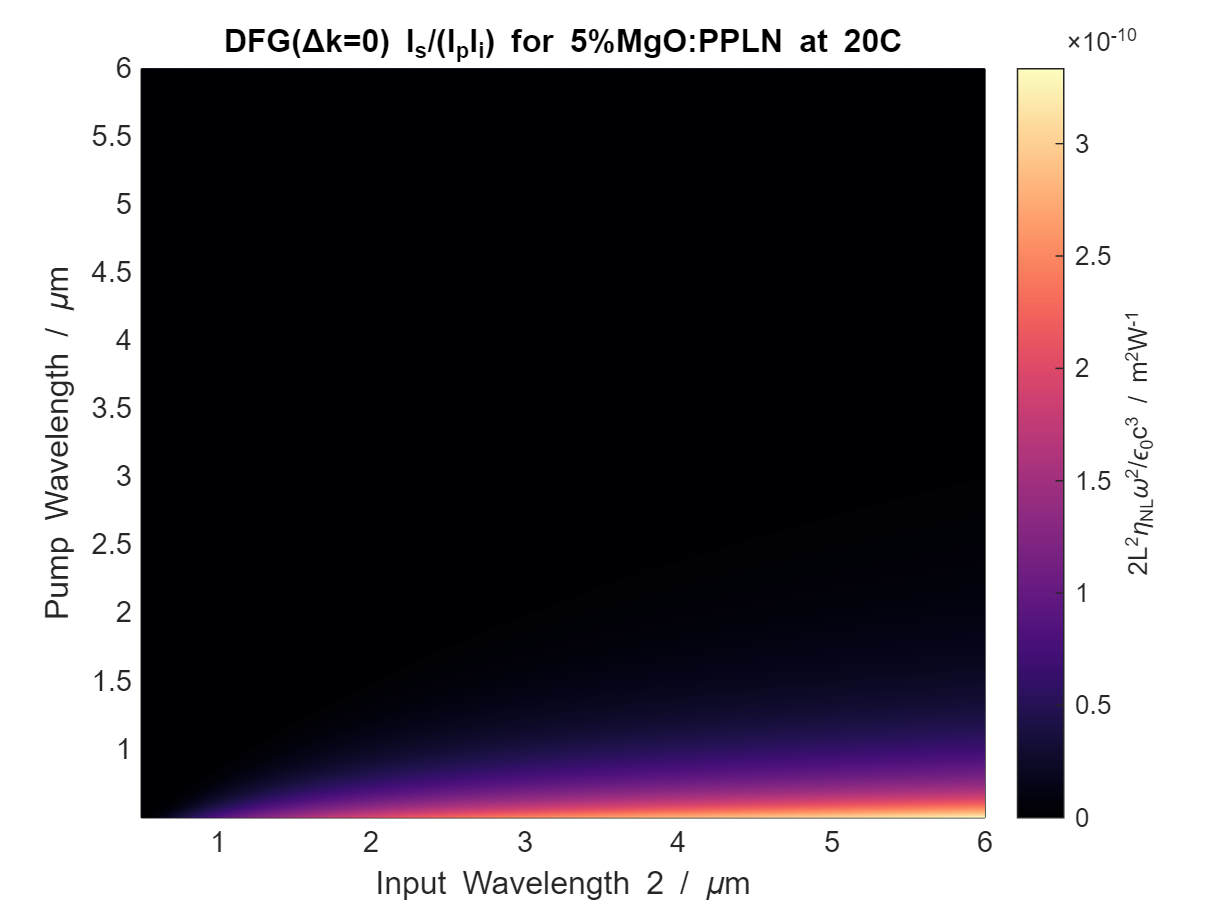

figure
if isscalar(lam_p_um)
	plot(lam_um,conv_dfg)
	xlim([lam_p_um 5])
else
	pcolor(lam_um,lam_um,conv_dfg)
	shading interp
	cb = colorbar;
	clims = clim;
	% clims(1) = 25;
	clim(clims);
	cb.Label.String = "2L^2\eta_{NL}\omega^2/\epsilon_0c^3 / m^2W^{-1}";
	ylabel("Pump Wavelength / \mum")
end
xlabel("Input Wavelength 2 / \mum")
title("DFG(\Deltak=0) I_s/(I_pI_i) for 5%MgO:PPLN at " + num2str(crystal.Bulk.Temperature,'%iC'))

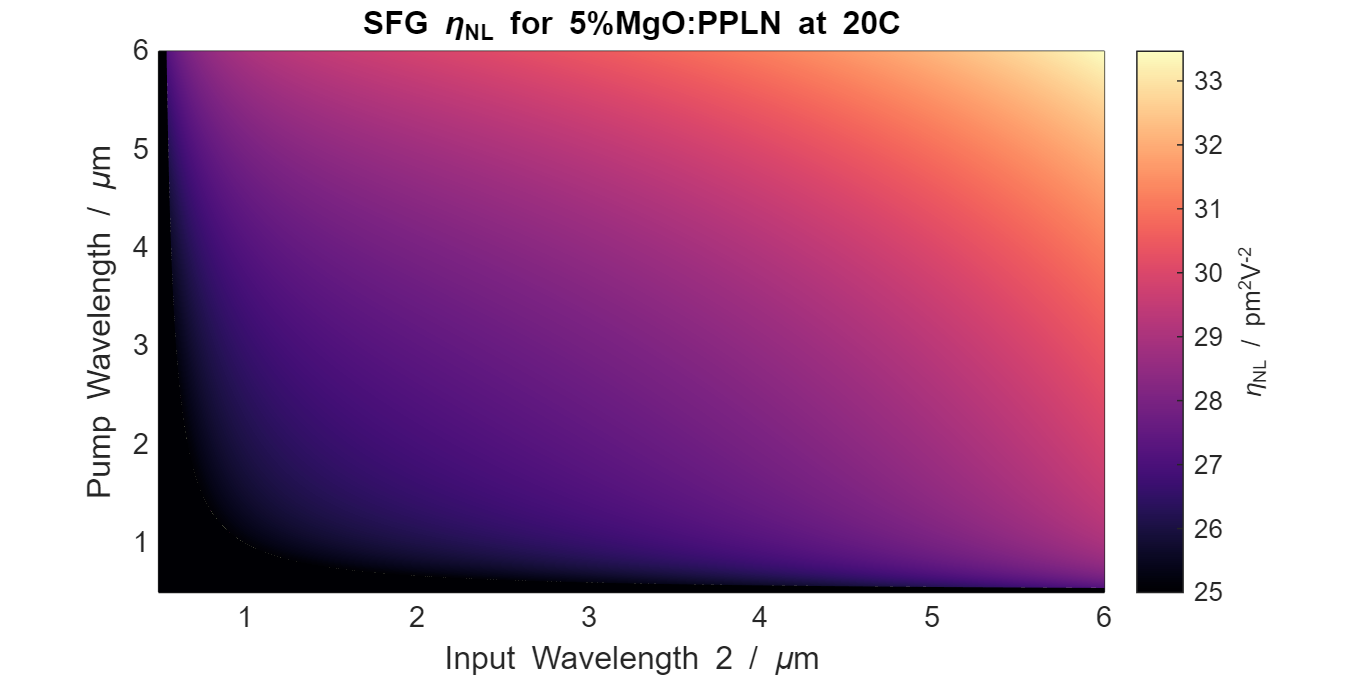

if isscalar(lam_p_um)
	plot(lam_um,fom_sfg)
	xlim([0.35 lam_p_um])
else
	pcolor(lam_um,lam_um,fom_sfg)
	shading interp
	cb = colorbar;
	clims = clim;
	clims(1) = 25;
	clim(clims);
	cb.Label.String = "\eta_{NL} / pm^2V^{-2}";
	ylabel("Pump Wavelength / \mum")
end
xlabel("Input Wavelength 2 / \mum")
title("SFG \eta_{NL} for 5%MgO:PPLN at " + num2str(crystal.Bulk.Temperature,'%iC'))

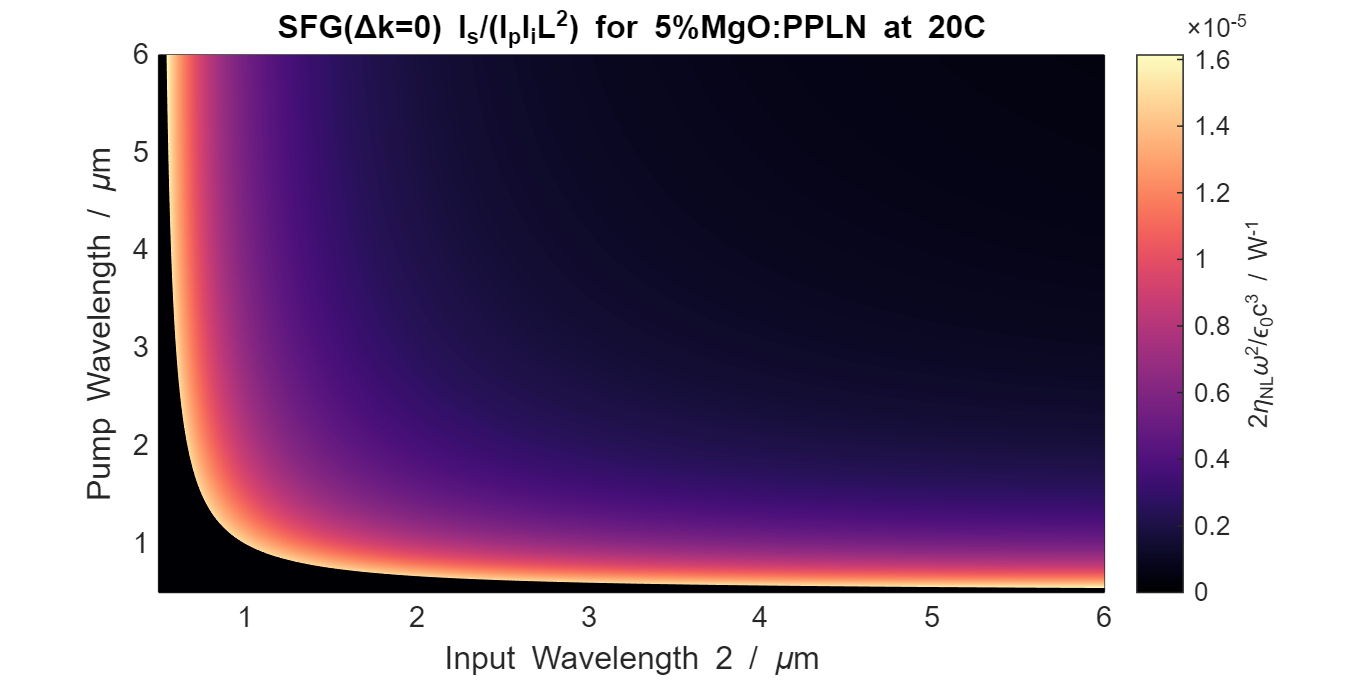

figure
if isscalar(lam_p_um)
	plot(lam_um,conv_sfg)
	xlim([lam_p_um 5])
else
	pcolor(lam_um,lam_um,conv_sfg)
	shading interp
	cb = colorbar;
	clims = clim;
	% clims(1) = 25;
	clim(clims);
	cb.Label.String = "2\eta_{NL}\omega^2/\epsilon_0c^3 / W^{-1}";
	ylabel("Pump Wavelength / \mum")
end
xlabel("Input Wavelength 2 / \mum")
title("SFG(\Deltak=0) I_s/(I_pI_iL^2) for 5%MgO:PPLN at " + num2str(crystal.Bulk.Temperature,'%iC'))